# [1.5. Кинематика](https://ru.wikipedia.org/wiki/%D0%9A%D0%B8%D0%BD%D0%B5%D0%BC%D0%B0%D1%82%D0%B8%D0%BA%D0%B0)

#### [Полярные координаты](https://ru.wikipedia.org/wiki/Полярная_система_координат) на плоскости

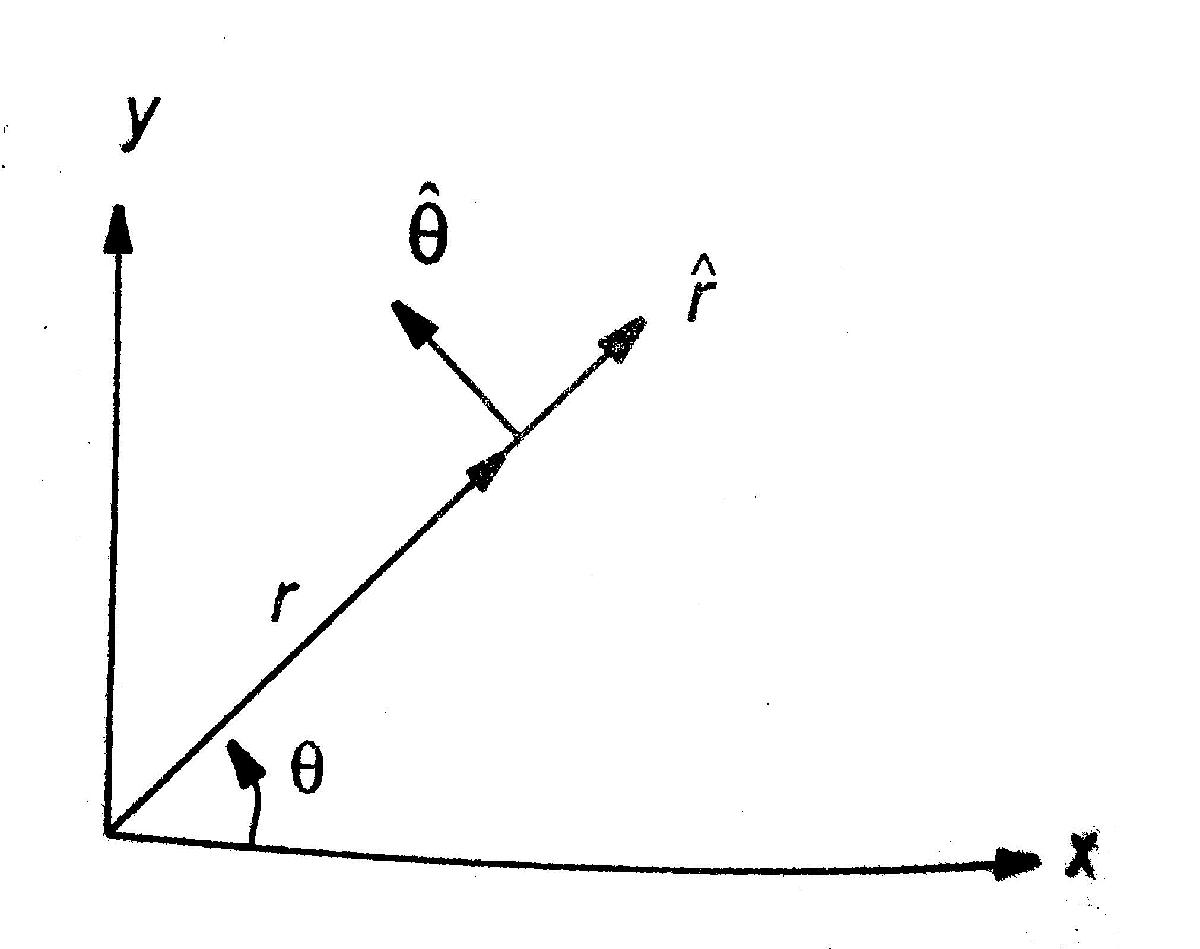


$$\mathit{\mathbf{r}}=r\;\hat{\mathit{\mathbf{r}}}$$


clear
syms t r theta d(f,x,n)
R=[r;0]

$$R = \left(\begin{array}{c} r\\ 0 \end{array}\right)$$


$$\dot{\mathit{\mathbf{r}}} =\dot{r} \;\hat{\mathit{\mathbf{r}}} +r\;\theta^˙ \;\theta^ˆ$$


R1d=[d(r,t,1);r*d(theta,t,1)]

$$R1d = \left(\begin{array}{c} d\left(r,t,1\right)\\ r\,d\left(\theta ,t,1\right) \end{array}\right)$$


$$\ddot{\mathit{\mathbf{r}}} =\left(\ddot{r} -r\;{\theta^˙ }^2 \right)\hat{\mathit{\mathbf{r}}} +\left(r\;\theta^¨ +2\;\dot{r} \;\theta^˙ \right)\theta^ˆ$$


R2d=[d(r,t,2)-r*d(theta,t,1)^2; (r*d(theta,t,2)+2*d(r,t,1)*d(theta,t,1))] 

$$R2d = \left(\begin{array}{c} d\left(r,t,2\right)-r\,{d\left(\theta ,t,1\right)}^{2}\\ r\,d\left(\theta ,t,2\right)+2\,d\left(r,t,1\right)\,d\left(\theta ,t,1\right) \end{array}\right)$$

*Особый случай*. Движение по окружности


$$r=\mathrm{const}$$



$$\ddot{r} =-r\;{\theta^˙ }^2 \;\hat{\mathit{\mathbf{r}}} +r\theta^¨ \;\theta^ˆ \;\;$$


syms r omega v
R2d=[-r*d(theta,t,1)^2; r*d(theta,t,2)]

$$R2d = \left(\begin{array}{c} -r\,{d\left(\theta ,t,1\right)}^{2}\\ r\,d\left(\theta ,t,2\right) \end{array}\right)$$

центростремительное ускорение = $-r\;{\theta^˙ }^2 =-r\;\omega^2 =\frac{v^2 }{r}$

% центростремительное ускорение =
-r*d(theta,t,1)^2==-r*omega^2==v^2/r

$$ans = \left(-r\,{d\left(\theta ,t,1\right)}^{2}=-\omega^{2}\,r\right)=\frac{v^{2}}{r}$$

#### [Цилиндрические координаты](https://ru.wikipedia.org/wiki/Цилиндрическая_система_координат)


$$\mathit{\mathbf{r}}=\rho \;\rho^ˆ +z\;\hat{z}$$


clear
syms t rho phi z d(f,x,n)
R=[rho;0;z]

$$R = \left(\begin{array}{c} \rho \\ 0\\ z \end{array}\right)$$


$$\dot{r} =\rho^˙ \;\rho^ˆ +\rho \;\varphi^˙ \;\varphi^ˆ +\dot{z} \;\hat{z}$$


Rd=[d(rho,t,1);rho*d(phi,t,1);d(z,t,1)]

$$Rd = \left(\begin{array}{c} d\left(\rho ,t,1\right)\\ \rho \,d\left(\varphi ,t,1\right)\\ d\left(z,t,1\right) \end{array}\right)$$


$$\ddot{\mathit{\mathbf{r}}} =\left(\rho^¨ -\rho \;{\varphi^˙ }^2 \right)\rho^ˆ +\left(\rho \;\varphi^¨ +2\;\rho^˙ \;\varphi^˙ \right)\varphi^ˆ +\ddot{z} \;\hat{\mathit{\mathbf{z}}}$$


R2d=[d(rho,t,2)-rho*d(phi,t,1)^2;...
    rho*d(phi,t,2)+2*d(rho,t,1)*d(phi,t,1);
    d(z,t,2)]

$$R2d = \left(\begin{array}{c} d\left(\rho ,t,2\right)-\rho \,{d\left(\varphi ,t,1\right)}^{2}\\ \rho \,d\left(\varphi ,t,2\right)+2\,d\left(\varphi ,t,1\right)\,d\left(\rho ,t,1\right)\\ d\left(z,t,2\right) \end{array}\right)$$

#### Вращение вокруг оси

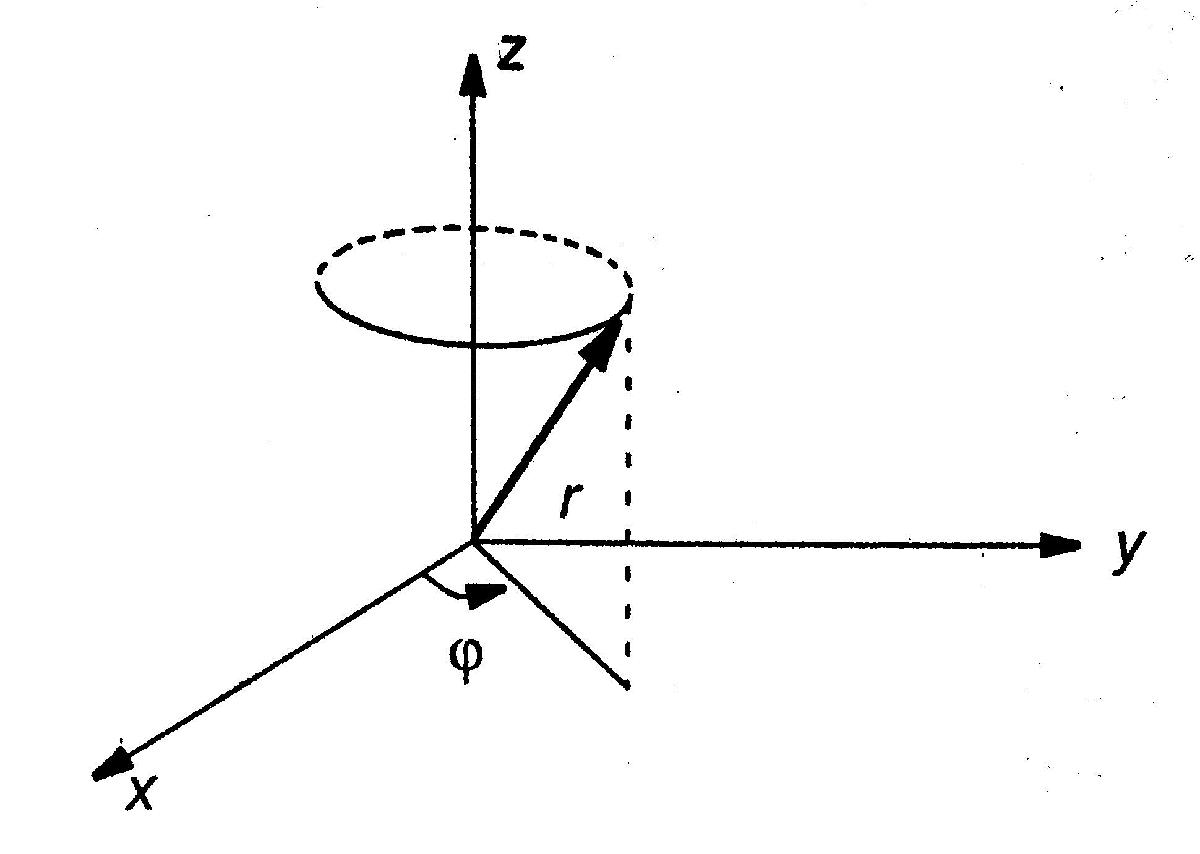


$$\mathit{\mathbf{v}}=\varphi^˙ \;\hat{\mathit{\mathbf{z}}}$$


nu=[0;0;d(phi,t,1)]

$$nu = \left(\begin{array}{c} 0\\ 0\\ d\left(\varphi ,t,1\right) \end{array}\right)$$


$$\dot{\mathit{\mathbf{r}}} =\omega \times \mathit{\mathbf{r}}$$


syms Rd omega r vprod(x,y)
d(r,t,1)==vprod(omega,r)

$$ans = d\left(r,t,1\right)=\mathrm{vprod}\left(\omega ,r\right)$$

#### [Сферические координаты](https://ru.wikipedia.org/wiki/Сферическая_система_координат)

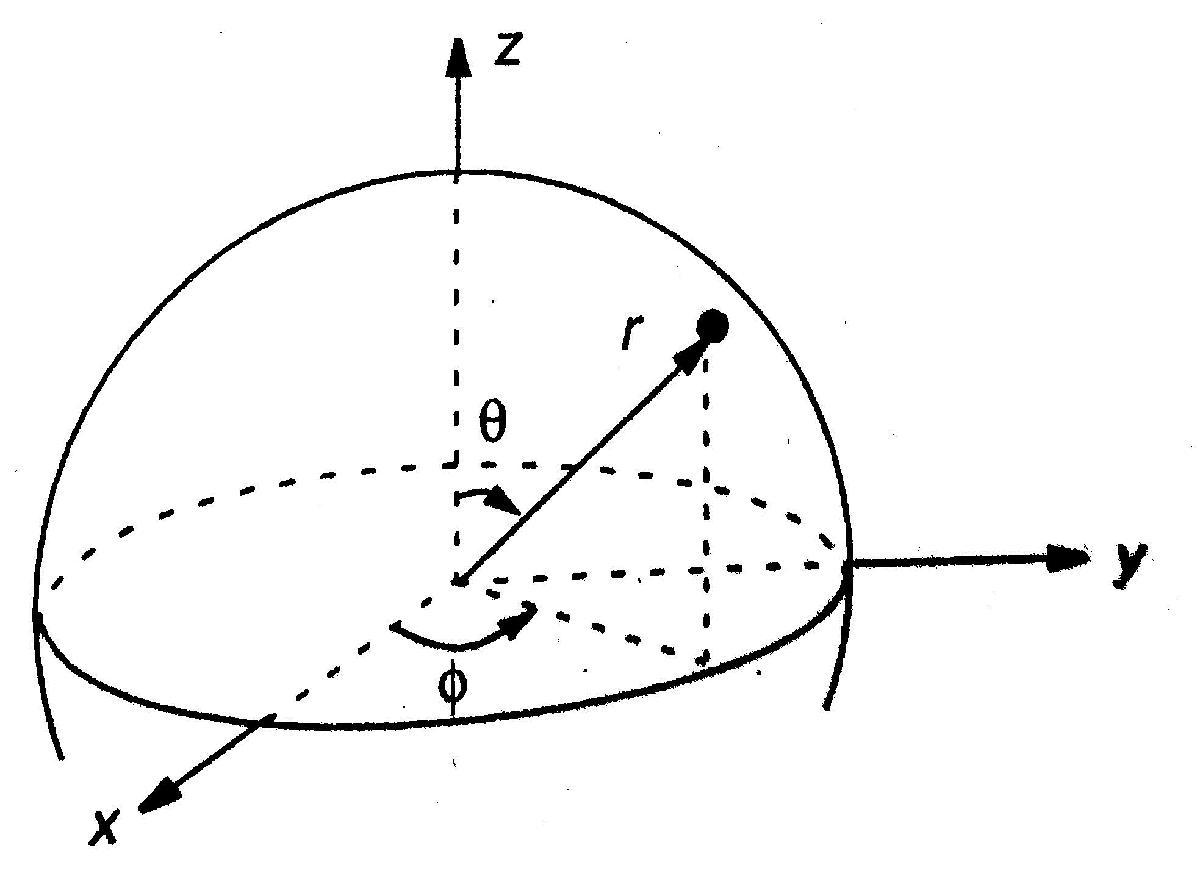


$$\mathit{\mathbf{r}}=r\;\hat{\mathit{\mathbf{r}}}$$


syms t r theta phi d(f,x,n)
R=[r;0;0]

$$R = \left(\begin{array}{c} r\\ 0\\ 0 \end{array}\right)$$


$$\dot{\mathit{\mathbf{r}}} =\dot{r} \;\hat{\mathit{\mathbf{r}}} +r\;\theta^˙ \;\theta^ˆ +r\dot{\;\varphi } \;\mathrm{sin}\;\theta \;\varphi^ˆ$$


Rd=[d(r,t,1);r*d(theta,t,1);r*d(phi,t,1)*sin(theta)]

$$Rd = \left(\begin{array}{c} d\left(r,t,1\right)\\ r\,d\left(\theta ,t,1\right)\\ r\,\sin\left(\theta \right)\,d\left(\varphi ,t,1\right) \end{array}\right)$$

Rd2=[d(r,t,2)-r*d(phi,t,1)^2*sin(theta)^2-r*d(theta,t,1)^2;...
    r*d(theta,t,2)+2*d(r,t,1)*d(theta,t,1)-r*d(phi,t,1)^2*sin(theta)*cos(theta);
    r*d(phi,t,2)*sin(theta)+2*d(r,t,1)*d(phi,t,1)*sin(theta)+2*r*d(theta,t,1)*d(phi,t,1)*cos(theta)]

$$Rd2 = \begin{array}{l} \left(\begin{array}{c} -r\,{\sin\left(\theta \right)}^{2}\,\sigma_{1}-r\,{d\left(\theta ,t,1\right)}^{2}+d\left(r,t,2\right)\\ -r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\sigma_{1}+r\,d\left(\theta ,t,2\right)+2\,d\left(r,t,1\right)\,d\left(\theta ,t,1\right)\\ r\,\sin\left(\theta \right)\,d\left(\varphi ,t,2\right)+2\,\sin\left(\theta \right)\,d\left(\varphi ,t,1\right)\,d\left(r,t,1\right)+2\,r\,\cos\left(\theta \right)\,d\left(\varphi ,t,1\right)\,d\left(\theta ,t,1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={d\left(\varphi ,t,1\right)}^{2} \end{array}$$

#### Плоское движение, тангенциальные и нормальные координаты

Мгновенный радиус кривизны

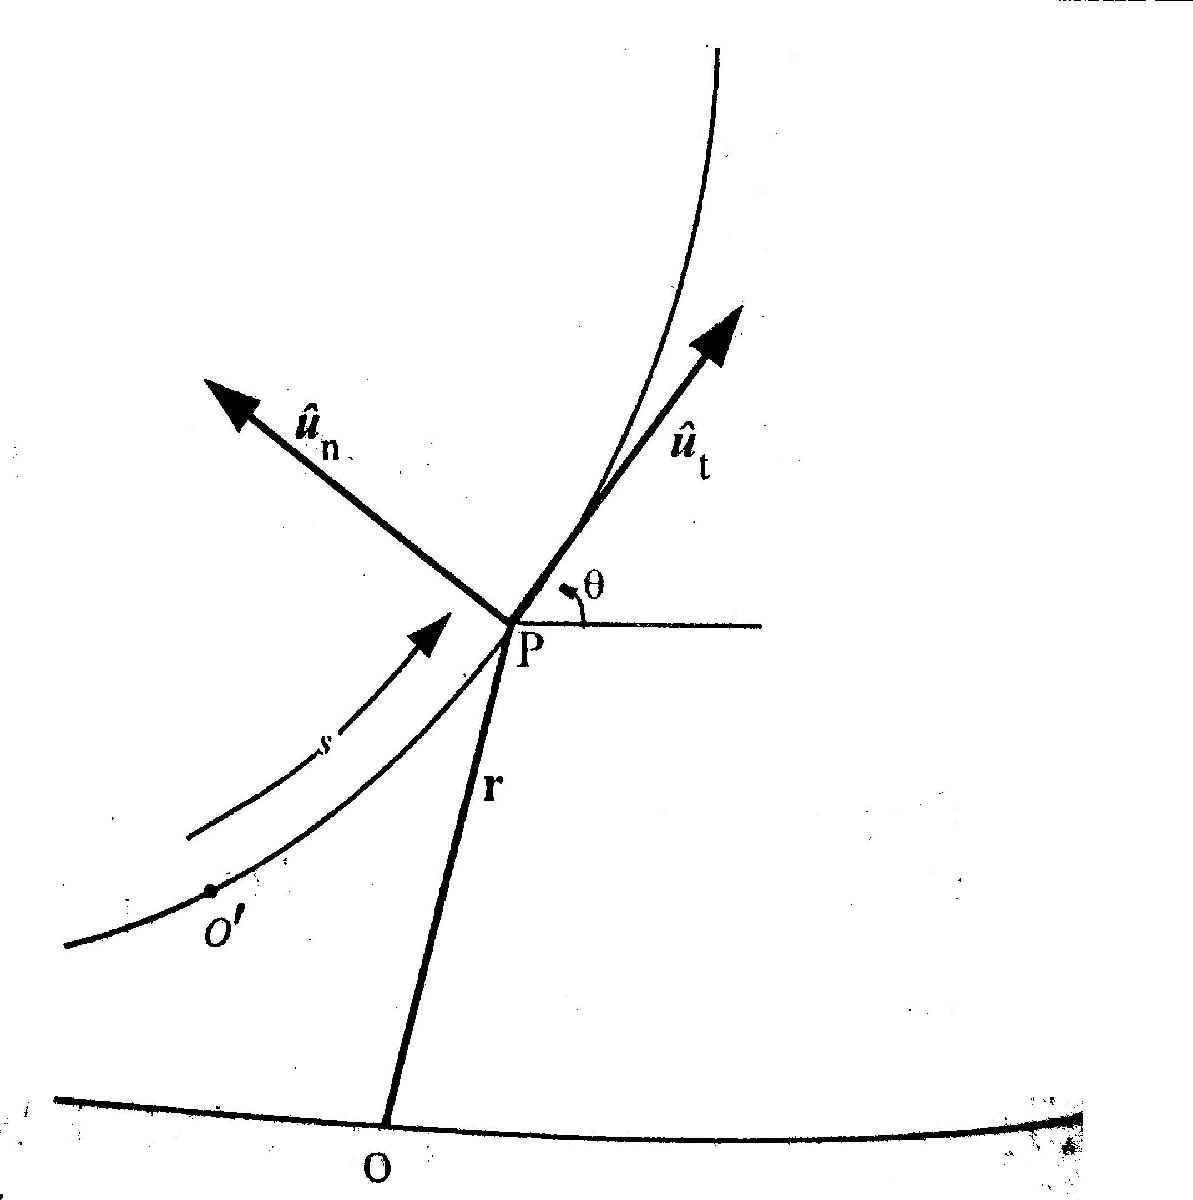

clear
syms theta s rho d(f,x,n)
rho==d(s,theta,1)

$$ans = \rho =d\left(s,\theta ,1\right)$$

% s - длина дуги
% theta - угол траектории

Скорость и ускорение относительно O

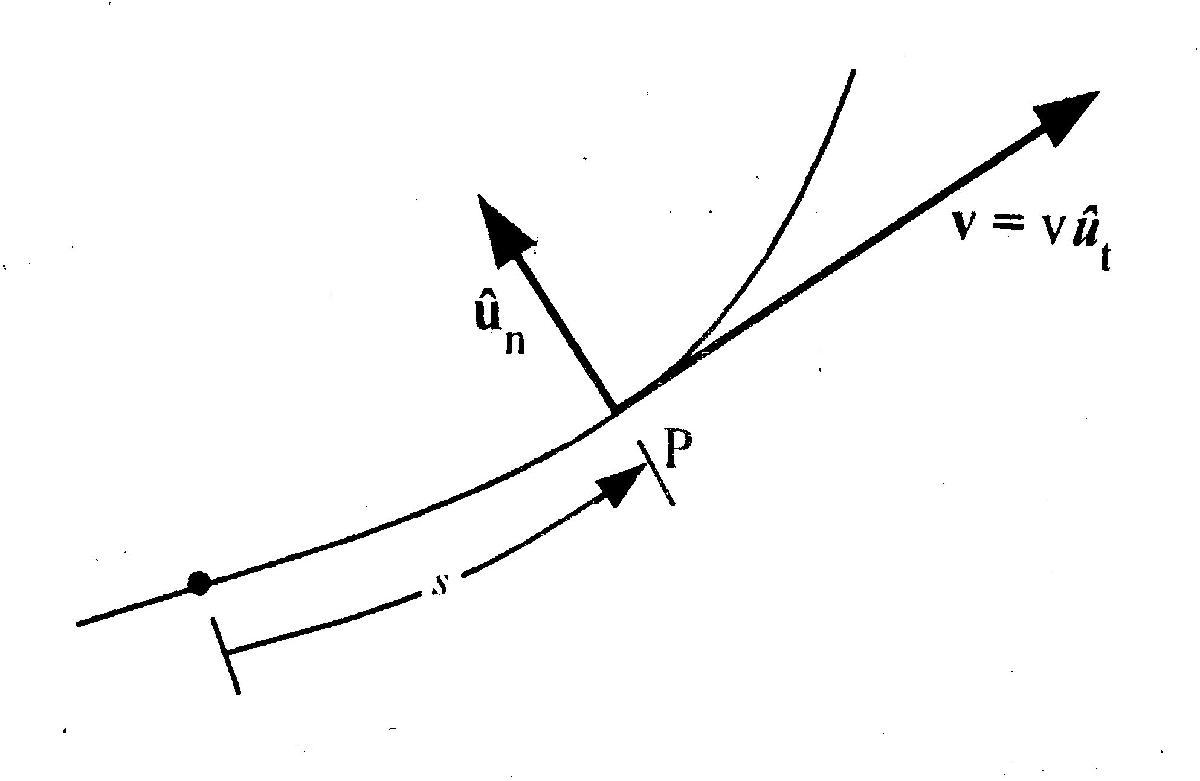


$$\mathit{\mathbf{v}}=v\;\hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{t}}} } =\dot{s} \;\hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{t}}} }$$


syms u_t u_n  V A t v s
V==v*u_t==d(s,t,1)*u_t

$$ans = \left(V=u_{t}\,v\right)=u_{t}\,d\left(s,t,1\right)$$


$$\mathit{\mathbf{a}}=a_t \hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{t}}} } +a_n {\hat{\mathit{\mathbf{u}}} }_{\mathit{\mathbf{n}}} =\dot{v} \;\hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{t}}} } +v\;\theta^˙ \;{\hat{\mathit{\mathbf{u}}} }_{\mathit{\mathbf{n}}} =\ddot{s} \;\hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{t}}} } +\frac{v^2 }{\rho }{\hat{\mathit{\mathbf{u}}} }_{\mathit{\mathbf{n}}}$$


syms a_t a_n v theta s rho A vd thetad s rho
A=[a_t;a_n]==[d(v,t,1);v*d(theta,t,1)]==[d(s,t,2);v^2/rho]

$$A = \left(\begin{array}{c} \left(a_{t}=d\left(v,t,1\right)\right)=d\left(s,t,2\right)\\ \left(a_{n}=v\,d\left(\theta ,t,1\right)\right)=\frac{v^{2}}{\rho } \end{array}\right)$$

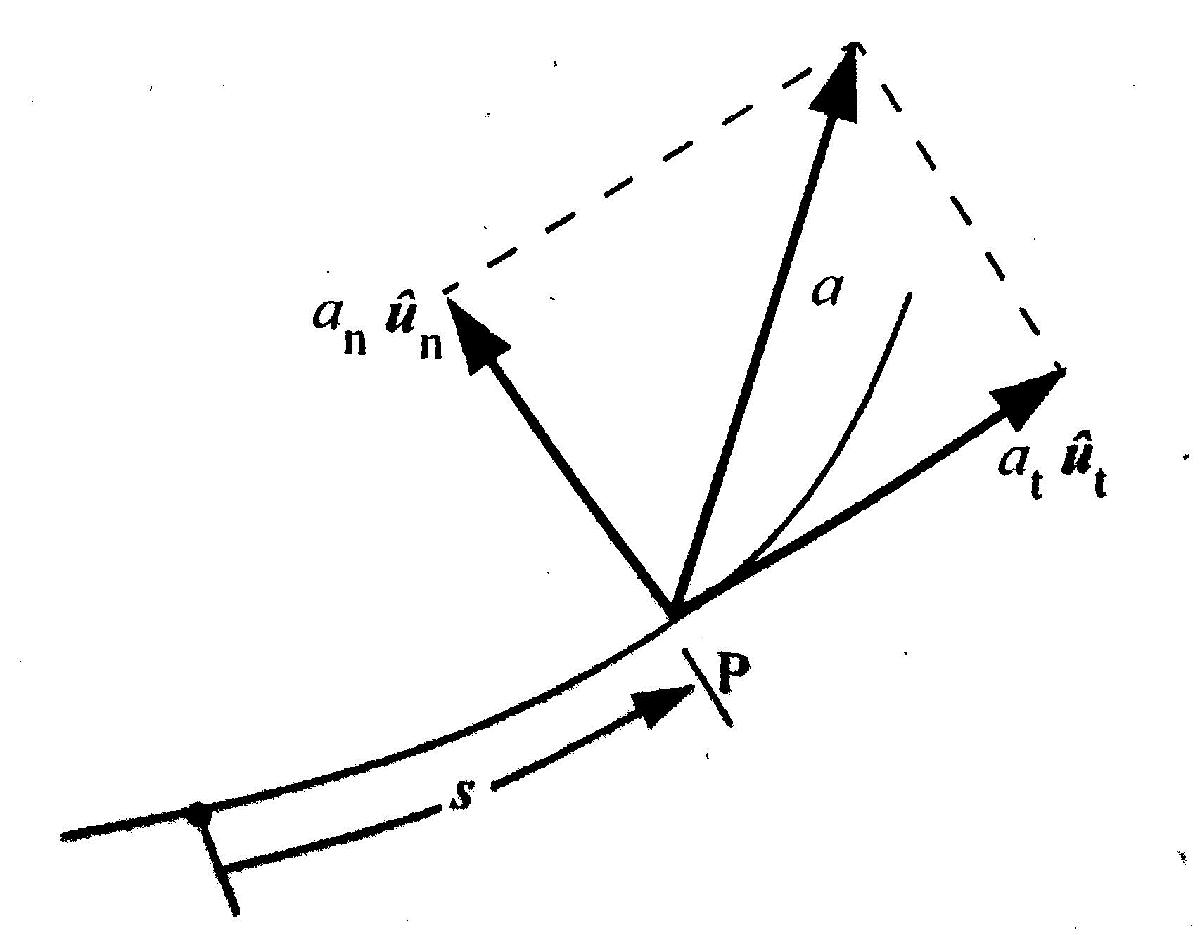

% Единичные вектора
% u_t - тангенциальный вектор
% u_n - нормальный вектор


$$\hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{p}}} } =\hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{t}}} } \times \hat{{\mathit{\mathbf{u}}}_{\mathit{\mathbf{n}}} }$$


syms vprod(x,y) u_p u_t u_n
u_p==vprod(u_t,u_n)

$$ans = u_{p}=\mathrm{vprod}\left(u_{t},u_{n}\right)$$